%% Clear workspace and close existing figures. Add SDK directories to Matlab path.
%close all; clear all; clc;

%% Importing the Data
% This example assumes you downloaded our example data sets
% (<https://www.tdt.com/files/examples/TDTExampleData.zip link>) and extracted
% it into the \TDTMatlabSDK\Examples\ directory. To import your own data, replace
% |BLOCKPATH| with the path to your own data block.
%
% In Synapse, you can find the block path in the database. Go to Menu > History.
% Find your block, then Right-Click > Copy path to clipboard.

%blockpath = 'U:\rdss_huxcui\Cui Lab - members\Undergraduate\Minh\Projects\mPFC-LHA\Fiber Photometry\Min3_Double_Fed-240122-110757\J7448_chowH-240124-103924'; %A1?
% blockpath = 'C:\minh\J7448_chowf_240126_103421'; % A2
%blockpath = 'C:\Users\udsingh\Desktop\minData\J7450_chowh-240124-115145'; % A3
%blockpath = 'C:\Users\udsingh\Desktop\minData\J7457_chowh-240124-130542'; % A4
%blockpath = 'C:\Users\udsingh\Desktop\minData\J7458_chowh-240124-140657'; %A5?
%blockpath = 'C:\Users\udsingh\Desktop\minData\J7459_chowh-240124-151855'; % A6
%blockpath = 'C:\Users\udsingh\Desktop\minData\J7461_chowh-240124-161928'; % A7

% Call the import function from the Matlab SDK
% https://www.tdt.com/support/sdk.html



% Environment variables
[root_dir,name,ext] = fileparts(cd);
PROJECT_PATH = fullfile(root_dir, name);
disp(PROJECT_PATH);

/home/benb/Documents/Cui_Lab/Minh_Fiber_Photometry_Analysis



SDKPATH = fullfile(PROJECT_PATH, 'TDTMatlabSDK');
addpath(genpath(SDKPATH));

% data
airpuff = 'airpuff';
chowf = 'chowf';
chowh = 'chowh';
hand = 'hand';
HFDf = 'HFDf';
HFDh = 'HFDh';

EXPERIMENT = airpuff;
SUBJECT = 'J7792_Airpuff-240228-145131';


blockpath = fullfile( ...
    PROJECT_PATH, ...
    'Data', ...
    EXPERIMENT, ...
    SUBJECT...
);
data = TDTbin2mat(blockpath);

Found Synapse note file: /home/benb/Documents/Cui_Lab/Minh_Fiber_Photometry_Analysis/Data/airpuff/J7792_Airpuff-240228-145131/Notes.txt


read from t=0.00s to t=2558.88s


%%
% Declare data stream and epoc names we will use downstream
% These are the field names for the relevant streams of the data struct
GCAMP = 'x465B';
ISOS = 'x405B';
%Lick = 'Lick';
chow = 'chow';


%% chow epocs entry 
data.epocs.chow.onset = [765.315317760000
768.524943360000
875.866849280000
925.836083200000
1016.54151168000
1066.23827968000
1102.52425216000
1131.36320512000
1179.66946304000
1291.81106176000
1351.85891328000
1390.98521600000
1512.27760640000];
data.epocs.chow.offset = data.epocs.chow.onset + .1;
data.epocs.chow.name = 'chow';
data.epocs.chow.data = [1
    1
    1
    1
    1
    1
    1
    1
    1
    1
    1
    1
    1];


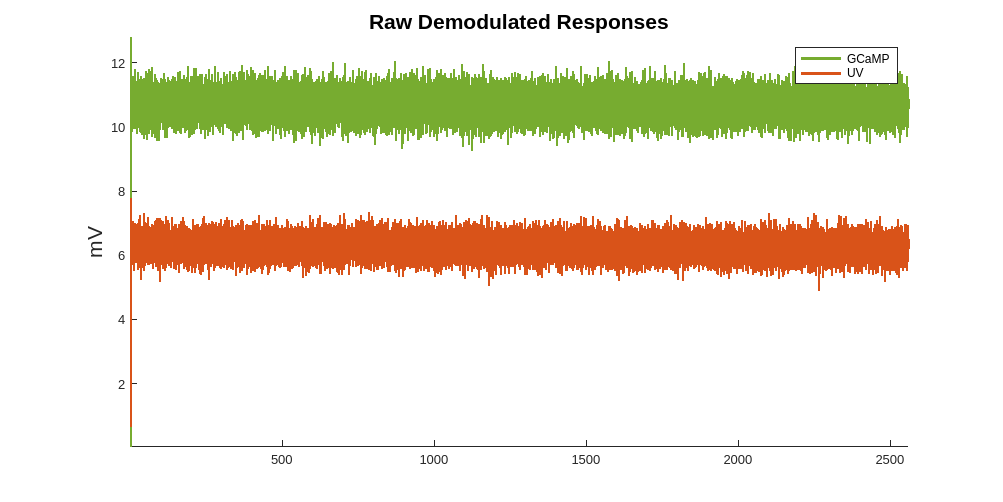

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Make some pretty colors for later plotting
% http://math.loyola.edu/~loberbro/matlab/html/colorsInMatlab.html
red = [0.8500, 0.3250, 0.0980];
green = [0.4660, 0.6740, 0.1880];
cyan = [0.3010, 0.7450, 0.9330];
gray1 = [.7 .7 .7];
gray2 = [.8 .8 .8];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Basic plotting and artifact removal
% Make a time array based on number of samples and sample freq of
% demodulated streams
time = (1:length(data.streams.(GCAMP).data))/data.streams.(GCAMP).fs;

%%
% Plot both unprocessed demodulated data streams
figure('Position',[100, 100, 800, 400])
hold on;
p1 = plot(time, data.streams.(GCAMP).data,'color',green,'LineWidth',2);
p2 = plot(time, data.streams.(ISOS).data,'color',red,'LineWidth',2);
title('Raw Demodulated Responses','fontsize',16);
ylabel('mV','fontsize',16);
axis tight;
legend([p1 p2], {'GCaMP','UV'});

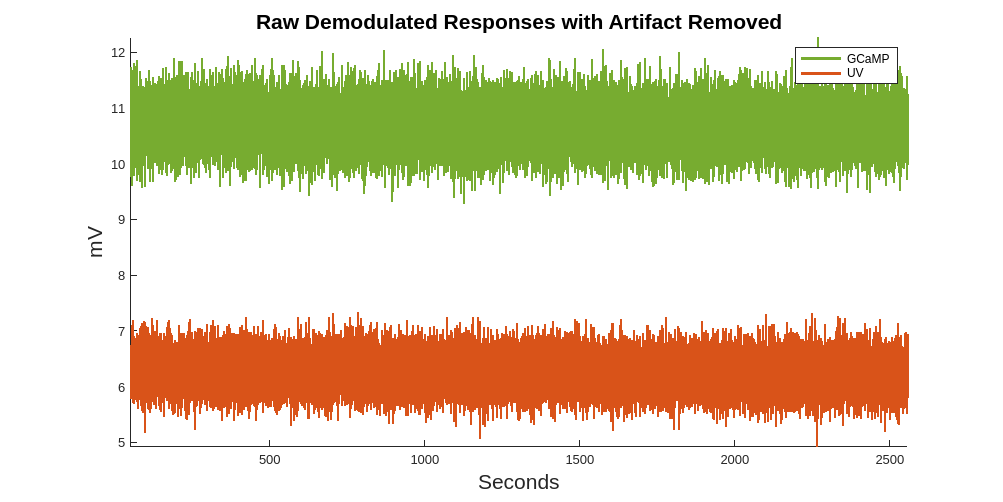



%% Artifact removal
% There is often a large artifact on the onset of LEDs turning on
% Remove data below a set time t
t = 50; % time threshold below which we will discard
ind = find(time>t,1); % find first index of when time crosses threshold
time = time(ind:end); % reformat vector to only include allowed time
data.streams.(GCAMP).data = data.streams.(GCAMP).data(ind:end);
data.streams.(ISOS).data = data.streams.(ISOS).data(ind:end);

%%
% Plot again at new time range
figure ('Position',[100, 100, 800, 400])
hold on;
p1 = plot(time, data.streams.(GCAMP).data,'color',green,'LineWidth',2); hold on; 
p2 = plot(time, data.streams.(ISOS).data,'color',red,'LineWidth',2);
title('Raw Demodulated Responses with Artifact Removed','fontsize',16);
xlabel('Seconds','fontsize',16)
ylabel('mV','fontsize',16);
axis tight;
legend([p1 p2], {'GCaMP','UV'});

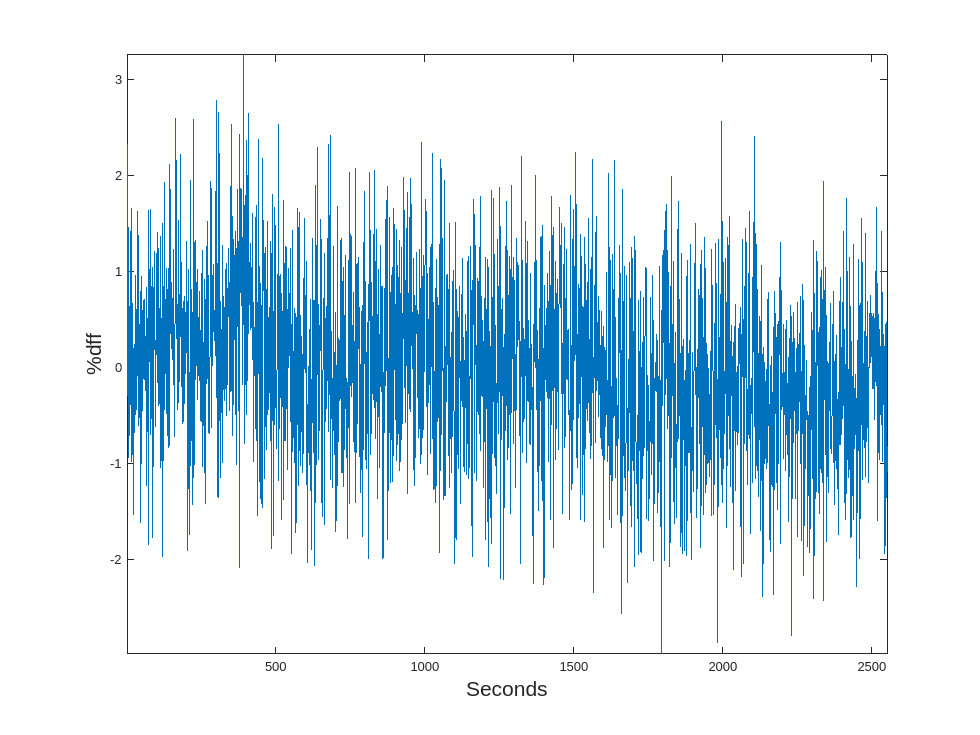


%% Downsample data doing local averaging
% Average around every Nth point and downsample Nx
%fr = data.streams.(GCAMP).fs;
N = 1000; % multiplicative for downsampling
data.streams.(GCAMP).data = arrayfun(@(i)...
    mean(data.streams.(GCAMP).data(i:i+N-1)),...
    1:N:length(data.streams.(GCAMP).data)-N+1);
data.streams.(ISOS).data = arrayfun(@(i)...
    mean(data.streams.(ISOS).data(i:i+N-1)),...
    1:N:length(data.streams.(ISOS).data)-N+1);

%%
% Decimate time array and match length to demodulated stream
time = time(1:N:end);
time = time(1:length(data.streams.(GCAMP).data));

%% Detrending and dFF
bls = polyfit(data.streams.(ISOS).data,data.streams.(GCAMP).data,1);
Y_fit_all = bls(1) .* data.streams.(ISOS).data + bls(2);
Y_dF_all = data.streams.(GCAMP).data - Y_fit_all; %dF (units mV) is not dFF

%%
% Full dFF according to Lerner et al. 2015
% http://dx.doi.org/10.1016/j.cell.2015.07.014
% dFF using 405 fit as baseline
figure
dFF = 100*(Y_dF_all)./Y_fit_all;
std_dFF = std(double(dFF));

plot(dFF)
axis tight;
xlabel('Seconds','fontsize',16)
ylabel('%dff','fontsize',16);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Now combine lick epocs that happen in close succession to make a
% single on/off event (a chow/lick BOUT).
% Top view logic: if difference between consecutive lick onsets is
% below a certain time threshold and there was more than one lick in a row,
% then consider it as one bout, otherwise it is its own bout. Also, make
% sure a minimum number of licks was reached to call it a bout.

%%

%% Time Filter Around Lick Bout Epocs
% Note that we are using dFF of the full time-series, not peri-event dFF
% where f0 is taken from a pre-event baseline period. That is done in
% another fiber photometry data analysis example.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
PRE_TIME1 = 5; % 20 seconds before event onset
POST_TIME1 = 5; % 20 seconds after
fs = data.streams.(GCAMP).fs/N; % recall we downsampled by N = 1000 earlier
% time span for peri-event filtering, PRE and POST
TRANGE = [-1*PRE_TIME1*floor(fs),POST_TIME1*floor(fs)];
BASELINE_PER = [-5 0]

BASELINE_PER =     -5     0


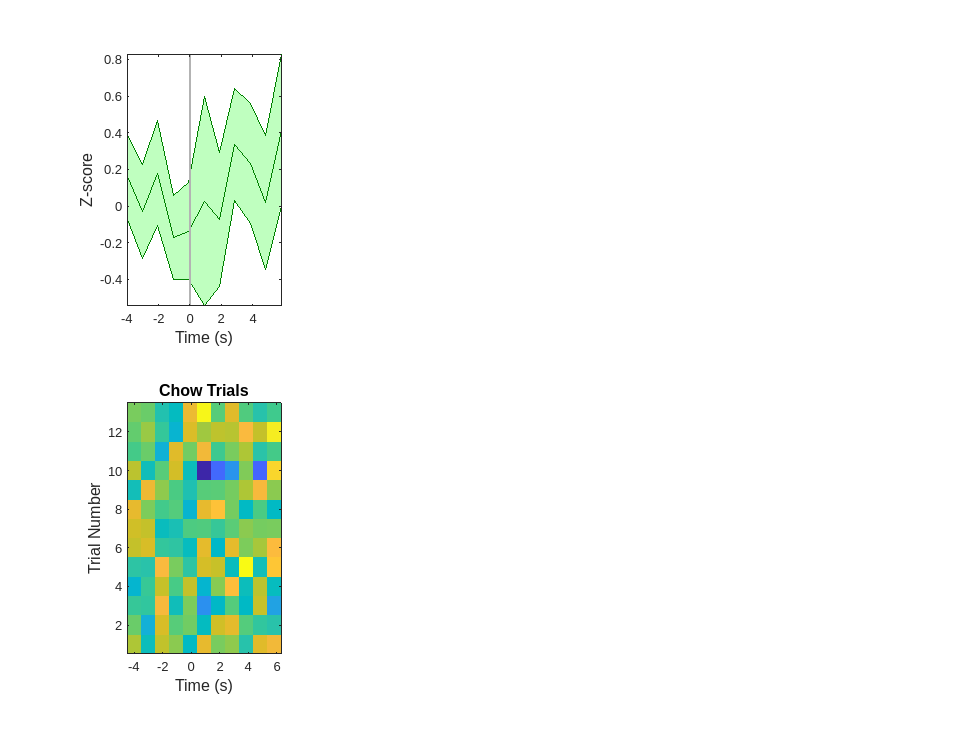


%% chow = chow %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pre-allocate memory (chow)
trials = numel(data.epocs.(chow).onset);
dFF_snips = cell(trials,1);
array_ind = zeros(trials,1);
pre_stim = zeros(trials,1);
post_stim = zeros(trials,1);

%%
% Make stream snips based on trigger onset
for i = 1:trials
    % If the bout cannot include pre-time seconds before event, make zero
    if data.epocs.(chow).onset(i) < PRE_TIME1
        dFF_snips{i} = single(zeros(1,(TRANGE(2)-TRANGE(1))));
        continue
    else
        % Find first time index after bout onset
        array_ind(i) = find(time > data.epocs.(chow).onset(i),1);
        
        % Find index corresponding to pre and post stim durations
        pre_stim(i) = array_ind(i) + TRANGE(1);
        post_stim(i) = array_ind(i) + TRANGE(2);
        dFF_snips{i} = dFF(pre_stim(i):post_stim(i));
    end
end

%%
% Make all snippet cells the same size based on minimum snippet length
minLength = min(cellfun('prodofsize', dFF_snips));
dFF_snips = cellfun(@(x) x(1:minLength), dFF_snips, 'UniformOutput',false);

% Convert to a matrix and get mean
chow_allSignals = cell2mat(dFF_snips);
mean_allSignals = mean(chow_allSignals);
std_allSignals = std(mean_allSignals);

% Make a time vector snippet for peri-events
peri_time1 = (1:length(mean_allSignals))/fs - PRE_TIME1;

% Make a Peri-Event Stimulus Plot and Heat Map
% based on z score of 405 fit subtracted 465

% Fitting 405 channel onto 465 channel to detrend signal bleaching
% Scale and fit data
% Algorithm sourced from Tom Davidson's Github:
% https://github.com/tjd2002/tjd-shared-code/blob/master/matlab/photometry/FP_normalize.m

chow_zall = zeros(size(chow_allSignals)); 
for i = 1:size(chow_allSignals,1)
%     ind = ts2(1,:) < BASELINE_PER(2) & ts2(1,:) > BASELINE_PER(1);
    ind = peri_time1(1,:) < BASELINE_PER(2) & peri_time1(1,:) > BASELINE_PER(1);
    zb = mean(chow_allSignals(i,ind)); % baseline period mean (-60sec to -0sec)
    zsd = std(chow_allSignals(i,ind)); % baseline period stdev
    chow_zall(i,:)=(chow_allSignals(i,:) - zb)/zsd; % Z score per bin
end

% Standard error of the z-score
zerror = std(chow_zall)/sqrt(size(chow_zall,1));
figure
ax1 = subplot(2,4,1);
% Fill band values for second subplot. Doing here to scale onset bar
% correctly
XX = [peri_time1, fliplr(peri_time1)];
YY = [mean(chow_zall)-zerror, fliplr(mean(chow_zall)+zerror)];
h = fill(XX, YY, 'g'); % plot this first for overlay purposes
hold on;
set(h, 'facealpha',0.25,'edgecolor', '[0 .5 0]')

%plot(peri_time1, smooth(mean(chow_zall)), 'color','[0 .5 0]', 'LineWidth', .1); hold on;
plot(peri_time1, (mean(chow_zall)), 'color','[0 .5 0]', 'LineWidth', .1); hold on;
line([0 0], [min(YY), max(YY)], 'Color', [.7 .7 .7], 'LineWidth', 2)

% Finish up the plot
axis tight
xlabel('Time (s)','FontSize',12)
ylabel('Z-score', 'FontSize', 12)

% Plot heat map
ax2 = subplot(2,4,5);
imagesc(peri_time1, 1, chow_zall); % this is the heatmap
set(gca,'YDir','normal') % put the trial numbers in better order on y-axis
title('Chow Trials','fontsize',12)
ylabel('Trial Number','fontsize',12)
xlabel('Time (s)','fontsize',12)
axis tight

%% Now Concatenate data

%% Save data to concatenate A1-7 data
ts1 = [0 -20 20]; % trial duration

chow_A1 = chow_zall;
% AUC_chow1 = []; % chow feeding  Animal 1
% AUC_chow1(1,1) = trapz(mean(chow_A1(:,peri_time1(1,:) < ts1(1) & peri_time1(1,:) > ts1(2))));
% AUC_chow1(1,2) = trapz(mean(chow_A1(:,peri_time1(1,:) > ts1(1) & peri_time1(1,:) < ts1(3))));

chow_A2 = chow_zall;
% AUC_chow2 = []; % chow feeding  Animal 2
% AUC_chow2(1,1) = trapz(mean(chow_A2(:,peri_time1(1,:) < ts1(1) & peri_time1(1,:) > ts1(2))));
% AUC_chow2(1,2) = trapz(mean(chow_A2(:,peri_time1(1,:) > ts1(1) & peri_time1(1,:) < ts1(3))));

% chow_A3 = chow_zall;
% AUC_chow3 = []; % chow feeding  Animal 3
% AUC_chow3(1,1) = trapz(mean(chow_A3(:,peri_time1(1,:) < ts1(1) & peri_time1(1,:) > ts1(2))));
% AUC_chow3(1,2) = trapz(mean(chow_A3(:,peri_time1(1,:) > ts1(1) & peri_time1(1,:) < ts1(3))));

% chow_A4 = chow_zall;
% AUC_chow4 = []; % chow feeding  Animal 4
% AUC_chow4(1,1) = trapz(mean(chow_A4(:,peri_time1(1,:) < ts1(1) & peri_time1(1,:) > ts1(2))));
% AUC_chow4(1,2) = trapz(mean(chow_A4(:,peri_time1(1,:) > ts1(1) & peri_time1(1,:) < ts1(3))));

% chow_A5 = chow_zall;
% AUC_chow5 = []; % chow feeding  Animal 5
% AUC_chow5(1,1) = trapz(mean(chow_A5(:,peri_time1(1,:) < ts1(1) & peri_time1(1,:) > ts1(2))));
% AUC_chow5(1,2) = trapz(mean(chow_A5(:,peri_time1(1,:) > ts1(1) & peri_time1(1,:) < ts1(3))));

% chow_A6 = chow_zall;
% AUC_chow6 = []; % chow feeding  Animal 6
% AUC_chow6(1,1) = trapz(mean(chow_A6(:,peri_time1(1,:) < ts1(1) & peri_time1(1,:) > ts1(2))));
% AUC_chow6(1,2) = trapz(mean(chow_A6(:,peri_time1(1,:) > ts1(1) & peri_time1(1,:) < ts1(3))));

% chow_A7 = chow_zall;
% AUC_chow7 = []; % chow feeding  Animal 7
% AUC_chow7(1,1) = trapz(mean(chow_A7(:,peri_time1(1,:) < ts1(1) & peri_time1(1,:) > ts1(2))));
% AUC_chow7(1,2) = trapz(mean(chow_A7(:,peri_time1(1,:) > ts1(1) & peri_time1(1,:) < ts1(3))));

%% Rerun to concatenate all the data included

%% Redefine final variables for FP_chow
FP_chow = [chow_A2; chow_A2]; %; chow_A3; chow_A4; chow_A6; chow_A7]; %% chow concatnate


%% Redefine final variables for AUC_chow 
% FP_AUC_bchow = [AUC_chow2(1,1); AUC_chow3(1,1); AUC_chow4(1,1); AUC_chow6(1,1); AUC_chow7(1,1);]; %% chow baseline
% FP_AUC_tchow = [AUC_chow2(1,2); AUC_chow3(1,2); AUC_chow4(1,2); AUC_chow6(1,2); AUC_chow7(1,2);]; %% chow trial

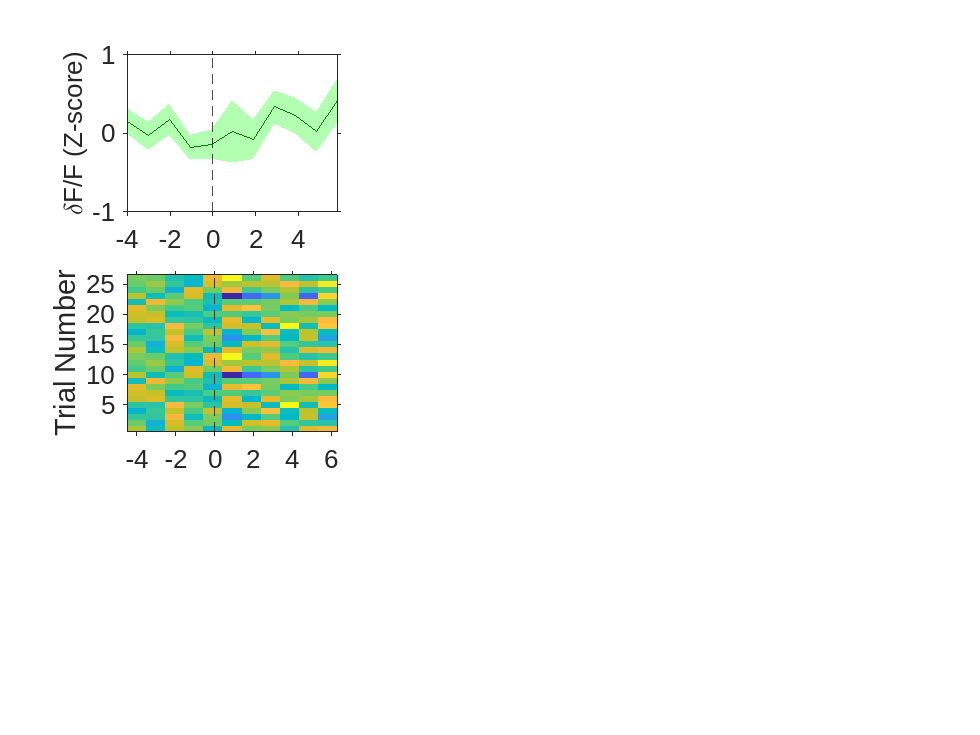

%%%% chow_tirals %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Standard error of the z-score
zerror = std(FP_chow)/sqrt(size(FP_chow,1));
figure
bx1 = subplot(3,3,1); %%%%%%%%%%%%%%%%%%%%%%%%%
% Fill band values for second subplot. Doing here to scale onset bar
% correctly
% % Make a time vector snippet for peri-events
% fs = 1
% peri_time1 = (1:length(FP_chow))/fs - PRE_TIME1;

XX = [peri_time1, fliplr(peri_time1)];
YY = [mean(FP_chow)-zerror, fliplr(mean(FP_chow)+zerror)];
h = fill(XX, YY, 'g'); % plot this first for overlay purposes
hold on;
set(h, 'facealpha',0.3,'edgecolor','none')

plot([peri_time1], mean(FP_chow), 'color','[0 .5 0]', 'LineWidth', .5); hold on;
xline(0, 'color','[0 0 0]', 'LineStyle', '--', 'LineWidth', 0.5);

% Finish up the plot
ax = gca; % current axes
ax.FontSize = 20;
ax.TickDir = 'out';
ax.TickLength = [0.02 0.02];
%ax.YLim = [-2 2];
axis tight
ylabel('\deltaF/F (Z-score)', 'fontSize', 20);
ylim([-1 1]);

% Plot heat map %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

bx2 = subplot(3,3,4); 
imagesc(peri_time1, 1, FP_chow); % this is the heatmap
set(gca,'YDir','normal') % put the trial numbers in better order on y-axis
%ylabel('\deltaF/F (Z-score)', 'fontSize', 20)
%xlim([-30 30]);
ylabel('Trial Number','fontsize',12)
xline(0, 'color','[0 0 0]', 'LineStyle', '--', 'LineWidth', 0.5);
%xticks([-60 -30 0 30 60]);
%yticks([]);
ax = gca; % current axes
ax.FontSize = 20;
ax.TickDir = 'out';
ax.TickLength = [0.02 0.02];
axis tight;


% bx3 = subplot(3,3,7);
% AUC_xxchow = []; % chow
% AUC_xxchow(1,1) = mean(FP_AUC_bchow);
% AUC_xxchow(1,2) = mean(FP_AUC_tchow);
% 
% 
% %put it on to a bar graph
% hBar1 = bar(AUC_xxchow,'FaceColor',[.8 .8 .8]);
% hBar2 = bar(AUC_xxchow,'FaceColor',[.8 .8 .8]);
% ylim([0 2]);
% ylabel('AUC','fontsize',25)

%end